% VortexPanelMethod.m
% This script uses the Vortex Panel Method to calculate the pressure coefficient of NACA 4412 airfoil

## Load airfoil coordinates

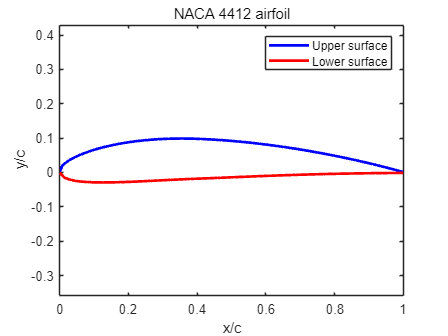

run('AirfoilNACA4412.m');

## Combine coordinates of the upper and lower surfaces

x_airfoil = [flip(xu(1:end-1)), xl(2:end)]; % Combine upper and lower surfaces
y_airfoil = [flip(yu(1:end-1)), yl(2:end)];

## Panel method setup

N = length(x_airfoil)-1; % Number of panels
panels = struct('x',{},'y',{},'xp',{},'yp',{},'theta',{},'gamma',{});

% Define panels
for i = 1:N
    panels(i).x = [x_airfoil(i), x_airfoil(i+1)];
    panels(i).y = [y_airfoil(i), y_airfoil(i+1)];
    panels(i).xp = (panels(i).x(1) + panels(i).x(2))/2; % Panel center x-coordinate
    panels(i).yp = (panels(i).y(1) + panels(i).y(2))/2; % Panel center y-coordinate
    dx = panels(i).x(2) - panels(i).x(1);
    dy = panels(i).y(2) - panels(i).y(1);
    panels(i).theta = atan2(dy,dx); % Panel angle
    panels(i).gamma = 0;         % Initialize vortex strength to zero
end

## Free stream velocity

V_inf = 100;
alpha = 0; % Angle of attack in degrees
alpha_rad = deg2rad(alpha);

## Calculate free stream velocity for each panel

b = zeros(N,1);
for i = 1:N
    % Calculate normal component of free stream velocity at panel center
    b(i) = -1*(V_inf * sin(pi + alpha_rad - panels(i).theta));
end

## Influence coefficient matrix

A = zeros(N,N);
Discard_number = round(N);
for i = 1:N
    if i ~= Discard_number
        for j = 1:N
            if i ~= j
                % Calculate induced velocity at panel i due to vortex on panel j
                [u,v] = induced_velocity(panels(j).xp,panels(j).yp,panels(i).xp,panels(i).yp,panels(j).x,panels(j).y);
                u_normal = u*sin(panels(i).theta) - v*cos(panels(i).theta);
                A(i,j) = u_normal;
            else
                A(i,j) = 0;
            end
        end
    end
end


## Kutta condition

A(Discard_number,1) = 1;
A(Discard_number,N) = 1;
b(Discard_number) = 0;

## Solve for vortex strength

gamma = A \ b;

## Calculate velocity diistribution

%V = zeros(N,1);
%   for i = 1:N
%       for j = 1:N
%           if j ~= i
%           [u,v] = induced_velocity(panels(j).xp,panels(j).yp,panels(i).xp,panels(i).yp,panels(j).x,panels(j).y);
%           V(i) = V(i) + gamma(i)*(u*cos(panels(i).theta) + v*sin(panels(i).theta));
%           end
%      end
%      V(i) = V(i) + V_inf*cos(alpha_rad + panels(i).theta);
%      % Add free stream velocity
%   end
V = -1 .* gamma;

## Calculate pressure coefficient

Cp = 1 - (V/V_inf).^2;

## Plot results

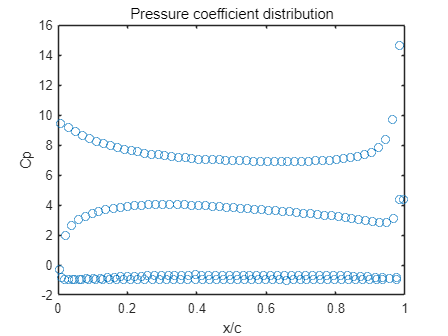

figure;
plot([panels.xp], -Cp, 'o');
xlabel('x/c');
ylabel('Cp');
title('Pressure coefficient distribution');

## Function for induced velocity

function [u,v] = induced_velocity(xv,yv,x,y,xvv,yvv)
    % Calculate insuced velocity at point (x,y) due to vortex at (xv,yv)
    dx = x - xv;
    dy = y - yv;
    dr = sqrt(dx.^2 + dy.^2);
    s = sqrt((xvv(2)-xvv(1))^2+(yvv(2)-yvv(1))^2);
    u = -s/(2*pi*(dr^2))*dy;
    v = s/(2*pi*(dr^2))*dx;
end